# **Алгоритм и модель работы классического последовательного обнаружителя (классический обнаружитель Вальда)**

## Инициализация параметров

Задаем исходные данные для расчета границ принятия решения: α, β, р0, р1

clear all
alpha = 10^(-6);%вероятность ложной тревоги вероятность правильного определения цели
betta = 0.5;%вероятность пропуска цели
p1 = 0.4;%параметр принятия решения для границы l1
p0 = 0.3;%параметр принятия решения для гранцы l0

## Определение границ l0 и l1

Для того чтобы избежать "ступенчатости" границ l0 и l1, зададим их заранее с большим шагом

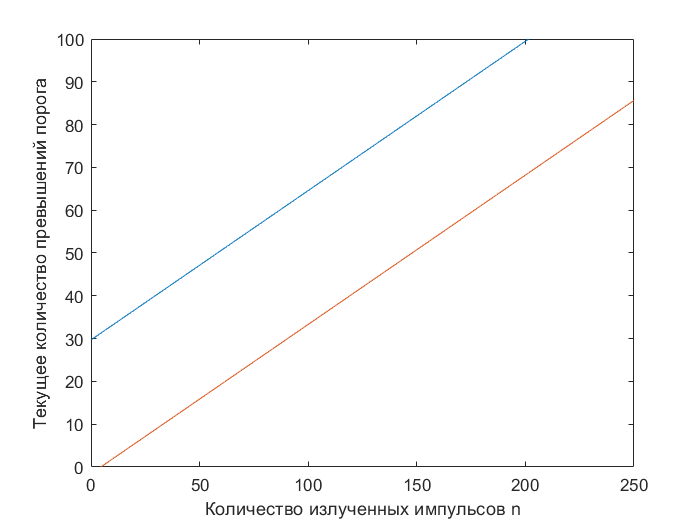

ns=0:0.1:500;
l1=(log((1-betta)/alpha)/(log(p1/p0)-log((1-p1)/(1-p0)))+ns*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
l0=(log((betta)/(1-alpha))/(log(p1/p0)-log((1-p1)/(1-p0)))+ns*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
plot(ns,l1,ns,l0)
xlim([0 250])
ylim([0 100])
xlabel('Количество излученных импульсов n');
ylabel('Текущее количество превышений порога');
hold on

## Определение цели с помощью классического алгоритма Вальда

ndim=1:1:3;%угловое положение луча
kdim=1:1:6;%каналы дальности
Ulim=6;%U_предельное
k=1;%счетчик углового направления
j=1;%счетчик канала дальности
for ndim = 1:3%сканируем цель в трех угловых положениях
   for kdim = 1:6%сканируем цель в шести каналах дальности по каждому из угловых положений
       if k==2 & j==3 %поставим нашу цель в квант во втором угловом положении и третем канале дальности
           q=10;%задаем большое значение сигнал/шум для точного определения цели
       else %остальные кванты
           q=1;%для остальных отношение сигнал/шум равно 1
       end
       i=1;
       n=0;%начальное значения числа излученых импульсов
       n1=0;%количество превышений U_порог
       l0=(log((betta)/(1-alpha))/(log(p1/p0)-log((1-p1)/(1-p0)))+n*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
       l1=(log((1-betta)/alpha)/(log(p1/p0)-log((1-p1)/(1-p0)))+n*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
       while n1>l0 && n1<l1 %если нарушается то нарушены границы - цель либо считается найденной, либо нет
           U=abs(normrnd(0,1.5))*q;%задаем значение отраженного сигнала в соответствии с нормальным распеределением
           nhist(i)=n;%запоминаем значения n
           n1hist(i)=n1;%запоминаем значения n1
           i=i+1;
           if U>Ulim%если выполняется то превышено U_порог
               n1=n1+1;
               n=n+1;
               Ulim=Ulim*1.05;%увеличивваем U_порог
           else%не превышено U_порог
               n1=n1+0;
               n=n+1;
               Ulim=Ulim*0.95;%уменьшаем U_порог
           end
           l0=(log((betta)/(1-alpha))/(log(p1/p0)-log((1-p1)/(1-p0)))+n*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
           l1=(log((1-betta)/alpha)/(log(p1/p0)-log((1-p1)/(1-p0)))+n*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
       end
       if n1<=l0%выводим результат исследования кванта
           x=['Цель отсутствует в кванте с координатами ',num2str(k),' и ',num2str(j)];
           disp(x)
       end
       Ulim=6;%возвращаем исходное значение для последующих квантов
       if n1>=l1%выводим результат исследования кванта
           x=['Цель найдена с координатами ',num2str(k),' и ',num2str(j)];
           disp(x)
       end
       plot(nhist,n1hist)%рисуем изменение n1 от n для каждого кванта на одном графике
       j=j+1;
   end
   j=1;
   k=k+1;
end

Цель отсутствует в кванте с координатами 1 и 1
Цель отсутствует в кванте с координатами 1 и 2
Цель отсутствует в кванте с координатами 1 и 3
Цель отсутствует в кванте с координатами 1 и 4
Цель отсутствует в кванте с координатами 1 и 5
Цель отсутствует в кванте с координатами 1 и 6
Цель отсутствует в кванте с координатами 2 и 1
Цель отсутствует в кванте с координатами 2 и 2


Цель найдена с координатами 2 и 3


Цель отсутствует в кванте с координатами 2 и 4
Цель отсутствует в кванте с координатами 2 и 5
Цель отсутствует в кванте с координатами 2 и 6
Цель отсутствует в кванте с координатами 3 и 1
Цель отсутствует в кванте с координатами 3 и 2
Цель отсутствует в кванте с координатами 3 и 3
Цель отсутствует в кванте с координатами 3 и 4
Цель отсутствует в кванте с координатами 3 и 5
Цель отсутствует в кванте с координатами 3 и 6


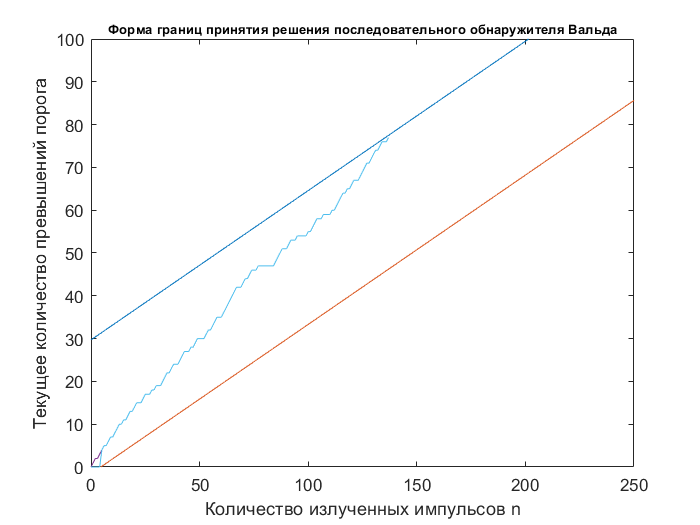

title('Форма границ принятия решения последовательного обнаружителя Вальда',"FontSize",8);
hold off

### Изобразим графически положение цели 

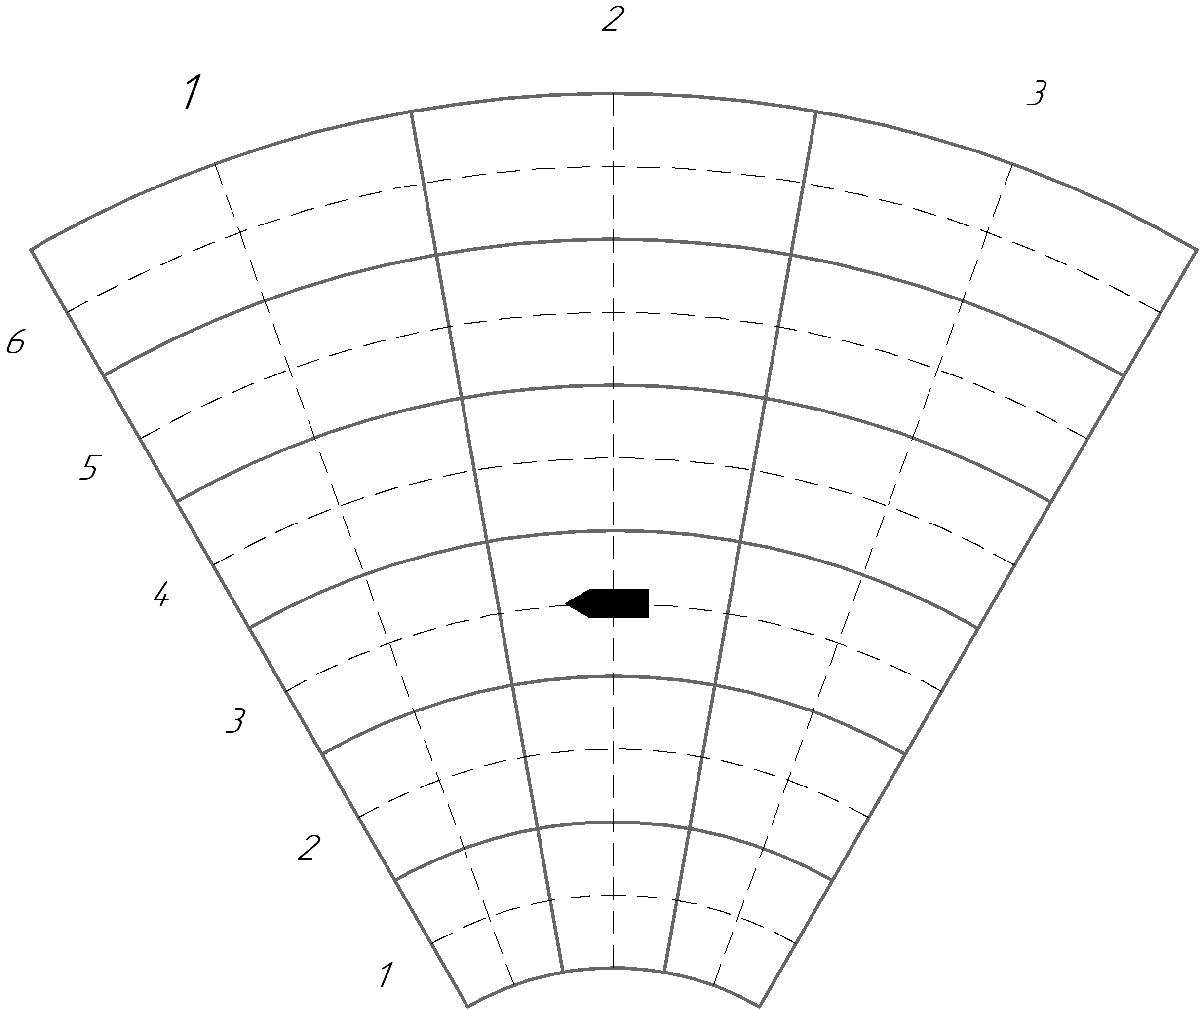

## Вычисление зависимости вероятности от соотношения сигнал/шум

Исследуем квант с целью. Задаем отношение сигнал/шум для группы реализаций, и увеличиваем его для каждой последующей группы реализаций, изменяя от 0 до 10 с заданным шагом 0.2. 

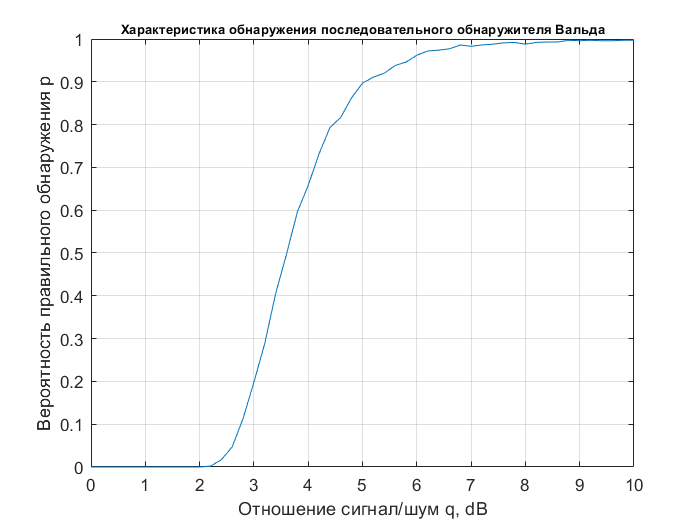

pcheck=1000;%количество реализаций в каждой точке сигнал/шум для определения вероятности
i=1;
pn=0;%начальное число удачных запусков из pcheck
Ulim=6;%граница U_пред
for qlim=0:0.2:10
    for ptest=1:1000%запускаем код 1000 раз для каждого qlim
        k=1;
        n=0;
        n1=0;
        l0=(log((betta)/(1-alpha))/(log(p1/p0)-log((1-p1)/(1-p0)))+n*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
        l1=(log((1-betta)/alpha)/(log(p1/p0)-log((1-p1)/(1-p0)))+n*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
        while n1>l0 && n1<l1
            U=abs(normrnd(0,1.5))*qlim;
            k=k+1;
            if U>Ulim
                n1=n1+1;
                n=n+1;
                Ulim=Ulim*1.05;
            else
                n1=n1+0;
                n=n+1;
                Ulim=Ulim*0.95;
            end
            l0=(log((betta)/(1-alpha))/(log(p1/p0)-log((1-p1)/(1-p0)))+n*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
            l1=(log((1-betta)/alpha)/(log(p1/p0)-log((1-p1)/(1-p0)))+n*((log((1-p0)/(1-p1))/(log(p1/p0)-log((1-p1)/(1-p0))))));
        end
        if n1<=l0
            pn=pn+0;%если не обнаружено, то оставляем то же значение
        end
        if n1>=l1
            pn=pn+1;%если обнаружено, то записываем в память
        end
        Ulim=6;
    end
    pp=pn/pcheck;%вычисляем вероятность для текущего qlim
    pphist(i)=pp;%запоминаем значение вероятнотсти
    qhist(i)=qlim;%запоминаем значение q
    i=i+1;
    pn=0;
end
plot(qhist,pphist)
xlabel('Отношение сигнал/шум q, dB');
ylabel('Вероятность правильного обнаружения p');
title('Характеристикa обнаружения последовательного обнаружителя Вальда',"FontSize",8);
grid on